# Import Geometry from text file

clear
proj = currentProject;

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Location", "Area"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Geom_Horn = readtable("Geom_Horn.txt", opts)

Geom_Horn = 29×2 table
    Location       Area   
    ________    __________

          0     0.00010157
    0.16826     0.00010157
    0.17343     0.00010268
    0.17859     0.00010426
    0.18376     0.00010536
    0.18892     0.00010783
    0.19409     0.00011401
    0.19925     0.00012424
    0.20442     0.00013753
    0.20958     0.00015268
    0.21475     0.00016878
    0.21991     0.00018544
    0.22508     0.00020276
    0.23024     0.00022138
    0.23541     0.00024235
    0.24057     0.00026662


## Clear temporary variables

clear opts


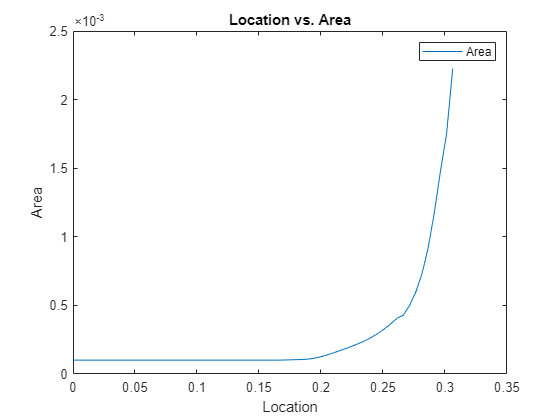

% Create plot of Geom_Horn.Location and Geom_Horn.Area
h = plot(Geom_Horn.Location,Geom_Horn.Area,'DisplayName','Area');

% Add xlabel, ylabel, title, and legend
xlabel('Location')
ylabel('Area')
title('Location vs. Area')
legend

run('Mat_Prop.m');

# **Acoustical components**

## Horn

ac.ho.x     = Geom_Horn.Location(3:end)-Geom_Horn.Location(2:end-1);
                                                    % Length of subsection
ac.ho.s     = Geom_Horn.Area(3:end);                % Area of subsection
ac.ho.n     = size(ac.ho.x);                        % No. of subsection

ac.ho.L     = air.rho0./ac.ho.s.*ac.ho.x/2;         % L in T network of subsection
ac.ho.C     = ac.ho.s/(air.rho0*air.c^2).*ac.ho.x;  % C in T network of subsection

%% Specify the model name
ac.ho.model = 'AC_Horn';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
ac.ho.io = getlinio(ac.ho.model);

%% Specify the operating point
% Use the model initial condition
ac.ho.op = operpoint(ac.ho.model);

%% Linearize the model
ac.ho.sys = linearize(ac.ho.model,ac.ho.io,ac.ho.op);

w = linspace(0,2*pi*5000,5001);
freq = w/(2*pi);
[ac.ho.mag, ac.ho.phase] = bode(ac.ho.sys,w);

ac.ho.Z = squeeze(ac.ho.mag)';
ac.ho.argZ = squeeze(ac.ho.phase)';



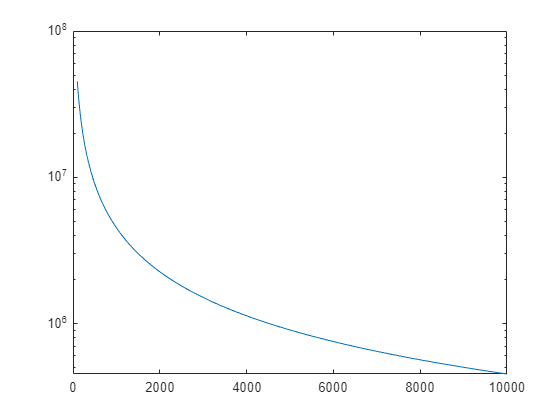

ac.ho.LTspice = readLTspice(strcat(proj.RootFolder, '/acoustical components/AC_Compressor_COMSOL_LTspice/AC -220722 - Compressor_.txt'),1,801);

semilogy(ac.ho.LTspice.freq, ac.ho.LTspice.abs_z_o);

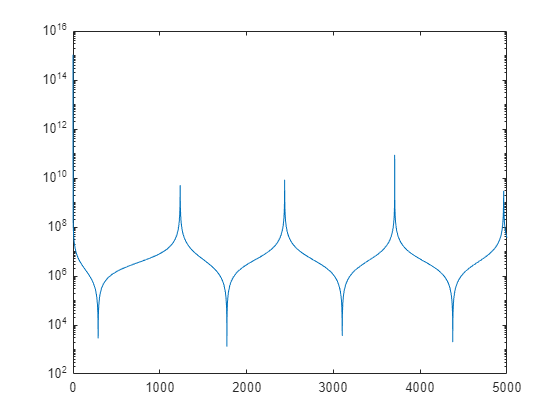



semilogy(freq,ac.ho.Z);

Geometry of parallel section

ac.ps.x     = Geom_Horn.Location(2);                % Length
ac.ps.s     = Geom_Horn.Area(2);                    % Area
ac.ps.n     = 20;                                   % No. of subsection

ac.ps.L     = air.rho0/ac.ps.s*(ac.ps.x/ac.ps.n);   % L in T network of subsection
ac.ps.C     = ac.ps.s/(air.rho0*air.c^2)*(ac.ps.x/ac.ps.n);
                                                    % C in T network of subsection

## Compressor (from COMSOL Multiphysics)

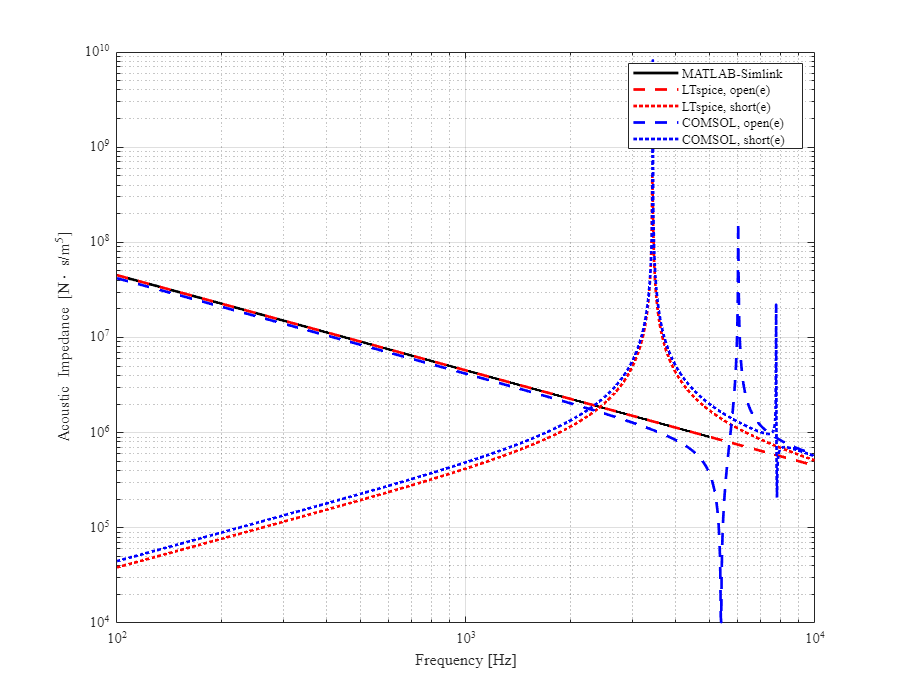

ac.co.L     = 38361.196102405345/(2*pi*100);
ac.co.C     = 1/(2*pi*100*4.518859697974938e7);

%% Specify the model name
ac.co.model = 'AC_Compressor';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
ac.co.io = getlinio(ac.co.model);

%% Specify the operating point
% Use the model initial condition
ac.co.op = operpoint(ac.co.model);

%% Linearize the model
ac.co.sys = linearize(ac.co.model,ac.co.io,ac.co.op);

w = linspace(0,2*pi*5000,5001);
freq = w/(2*pi);
[ac.co.mag, ac.co.phase] = bode(ac.co.sys,w);

ac.co.Z = squeeze(ac.co.mag)';
ac.co.argZ = squeeze(ac.co.phase)';

ac.ho.LTspice = readLTspice(strcat(proj.RootFolder,'/acoustical components/AC_Compressor_COMSOL_LTspice/AC -220722 - Compressor_.txt'),1,801);

ac.ho.COMSOL.open   = readCOMSOL(strcat(proj.RootFolder,'/acoustical components/AC_Compressor_COMSOL_LTspice/AC -220722 - Compressor, 2DX, open(e), abs(Z).txt'),9);
ac.ho.COMSOL.short  = readCOMSOL(strcat(proj.RootFolder,'/acoustical components/AC_Compressor_COMSOL_LTspice/AC -220722 - Compressor, 2DX, short(e), abs(Z).txt'),9);

plotcompZ(freq,ac.co.Z,...
    [ac.ho.LTspice.freq ac.ho.LTspice.freq],[ac.ho.LTspice.abs_z_o ac.ho.LTspice.abs_z_s],...
    [ac.ho.COMSOL.open.freq ac.ho.COMSOL.short.freq], [ac.ho.COMSOL.open.value ac.ho.COMSOL.short.value],...
    1e2,1e4,'log');


% semilogy(freq,ac.co.Z,'DisplayName','MATLAB-Simlink');
% hold on
% semilogy(ac.ho.LTspice.freq, ac.ho.LTspice.abs_z_o,'DisplayName','LTspice, open(e)');
% semilogy(ac.ho.LTspice.freq, ac.ho.LTspice.abs_z_s,'DisplayName','LTspice, short(e)');
% semilogy(ac.ho.COMSOL.open.freq, ac.ho.COMSOL.open.value,'DisplayName','COMSOL, open(e)');
% semilogy(ac.ho.COMSOL.short.freq, ac.ho.COMSOL.short.value,'DisplayName','COMSOL, short(e)');
% hold off







Geomtery of mouth (plane circular piston in infinite baffle)

**Need to implement 6th order radiation impedance**

ac.rad.s    = Geom_Horn.Area(end);
ac.rad.a    = sqrt(ac.rad.s/pi);

ac.rad.Rm1  = 1.386*ac.rad.a^2*air.rho0*air.c;
ac.rad.Rm2  = ac.rad.s*air.rho0*air.c;
ac.rad.Cm1  = 1.89/(pi*ac.rad.a*air.rho0*air.c^2);
ac.rad.Mm1  = 8*ac.rad.a^3*air.rho0/3;

**make the impedance check of components in acoustical doamin**

SPL check ok !

%% Specify the model name
model = 'AC_Test';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
io = getlinio(model);

%% Specify the operating point
% Use the model initial condition
op = operpoint(model);

%% Linearize the model
sys = linearize(model,io,op);

w = linspace(0,2*pi*5000,5001);
[mag, phase] = bode(sys,w);
vel = squeeze(mag)';
freq = w/(2*pi);
sp = vel.*freq*air.rho0/air.p_ref/sqrt(2);
plot(freq,mag2db(sp));

## Mechano-acoustical coupling

ma.co.DA    = 0.0036417751495247705;

## Mechanical components

%% Armature and diaphragm
me.ad.M    = 0.028596625123380574;  % Mass,                 [kg]
me.ad.K    = [134757.51424041812   7.399527807648116E7 1.0743542290213011E11 0 0];
                                    % Spring coefficients,  [N/m]
me.ad.R    = 1;                     % Damping coefficient,  [N.s/m]

%% Spring swtich from the experiment result (FD curve of spring)
me.sw.K_pt  = 31e3;                 % Pretensioned-spring coefficients, [N/m]
me.sw.K     = 7e3;                  % Spring coefficients,  [N/m]

%% Specify the model name
me.model = 'ME_Diaphragm';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
io = getlinio(me.model);

%% Specify the operating point
% Use the model initial condition
op = operpoint(me.model);

%% Linearize the model
me.sys = linearize(me.model,io,op);

%% Plot the resulting linearization
bode(me.sys,w);

## Electro-mechanical coupling

%% Spring swtich 
em.sw.x_on_pt   = -70e-6;   % Transition position from spring switch free to pretensioned,  [m]
em.sw.x_off     = -170e-6;  % Transition position from spring switch pretensioned to off,   [m]
em.sw.l_arc     = 80e-6;    % Arc length

## Electrical components

%% Coil
el.coil.Ls  = 2e-3;         % Coil series inductance,       [H]
el.coil.Rs  = 550e-3;       % Coil series resistance,       [Ohm]

%% Power supply
el.ps.V     = 12;           % Power supply voltage,         [V]

%% Switch
el.sw.R_on  = 1e-3;         % On state switch resistance,   [Ohm]
el.sw.R_off = 1e7;          % Off state switch resistance,  [Ohm]

